# Mesh Analysis

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)

**Learning Goals**

- Use mesh analysis to compute currents through a linear circuit.

- Solve the matrix form of circuit equations in MATLAB.

- Model and analyze linear circuits in Simscape.

## Overview

If a linear circuit has only one loop, it is typically a simple task to solve for the current. However, if the circuit has several branches, the current flowing through each branch is not obvious. Mesh analysis is a technique that solves this problem. You can use mesh analysis to solve for the currents flowing through a linear circuit with multiple branches. In the essential step of this technique, Kirchhoff's voltage law is applied to identify an equation for each mesh (a *mesh* is any closed loop through the circuit).

### **Kirchhoff's voltage law (KVL)**

The sum of voltages around a closed loop of a circuit (known as a mesh) is zero. Mathematically:


$$\sum_{k} V_k = 0$$


where $V_k$ is the potential difference across the $k^{th}$ element of the loop. Applying Ohm's law gives the potential drop across each resistor: $V = IR$.

 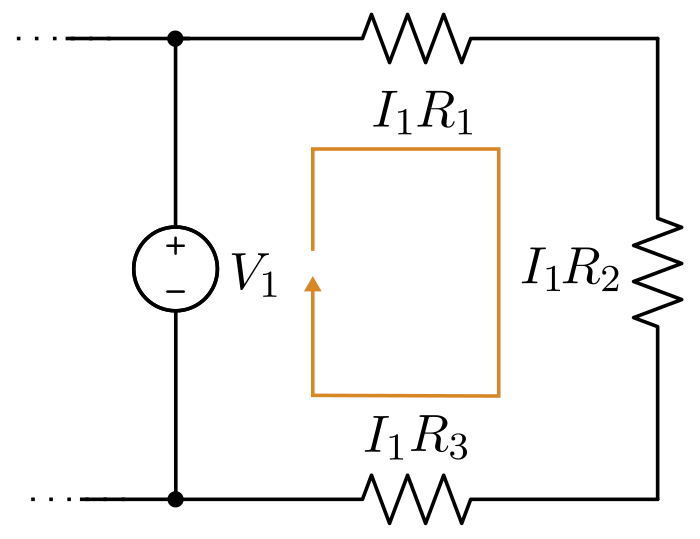

*The potential drop across the resistors in this closed loop must equal the potential generated by the voltage source: *$-V_1 + I_1 R_1 + I_1 R_2 + I_1 R_3 = 0$

### **Steps**

There are three major steps in mesh analysis:

- Define a current for each essential mesh.

- Write an equation for each essential mesh by applying KVL.

- Set up a matrix equation for the currents and solve.

In the first step, you define a current variable for each essential mesh. An *essential mesh *is a circuit loop that does not contain other loops.

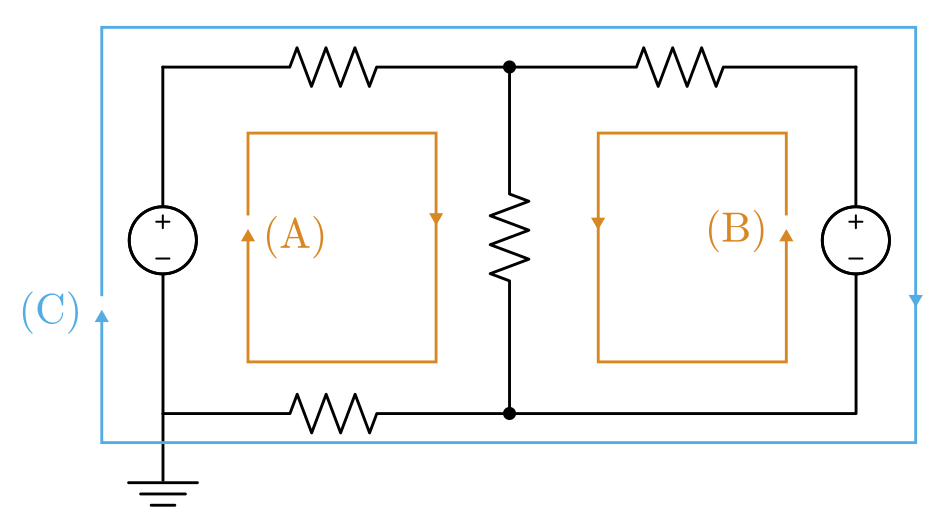

*Example circuit. The two interior meshes (A) and (B) are essential. The outer mesh (C) contains the inner meshes and is therefore unessential.*

With the meshes identified, you can define a current variable for each mesh – for example, $I_A$ and $I_B$. Note that, while you must assign a direction for the current, the direction is arbitrary. As long as you use the variable consistently, the selected direction is unimportant.

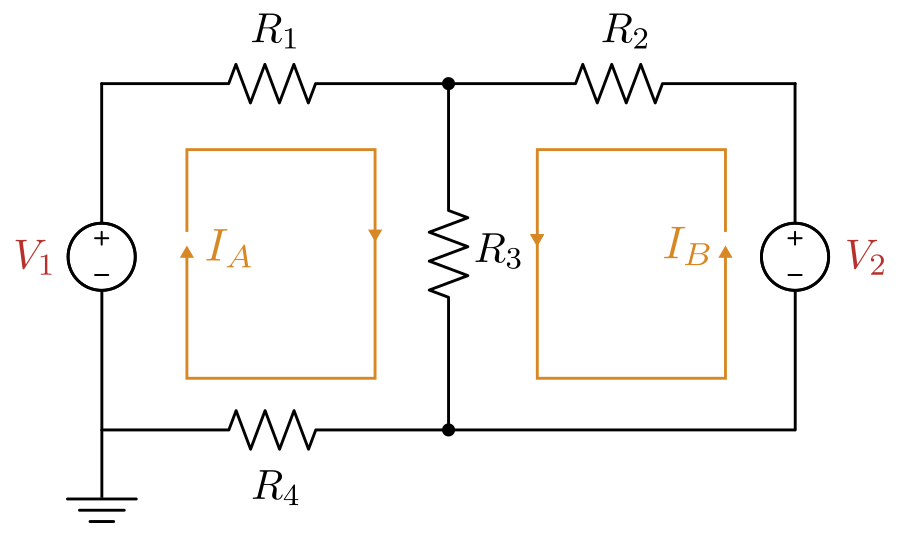

*Example circuit with mesh currents *$I_A$ and $I_B$.

Applying KVL to mesh (A) yields 

 
$$-V_1 + I_A R_1 + (I_A + I_B)\cdot R_3 + I_A R_4 = 0$$


**Note:** The actual current flowing a circuit element may equal a sum of several mesh currents. In this case, the current flowing through $R_3$ is the sum $I_A + I_B$. Mesh currents are logical partitions and can be easily confused with branch currents.

The derived equation has two unknowns: $I_A$ and $I_B$. To be solved, an additional equation is needed. Applying KVL again to the second essential mesh will yield the necessary equation. To solve the resulting system, you can define a matrix system. Matrices provide a natural framework: they can concisely capture the many linear equations that model the circuit network. In the following example, the matrix form is derived and used to solve for the mesh currents.

## **Example **

Use mesh analysis to solve for the currents through the circuit with the given values.

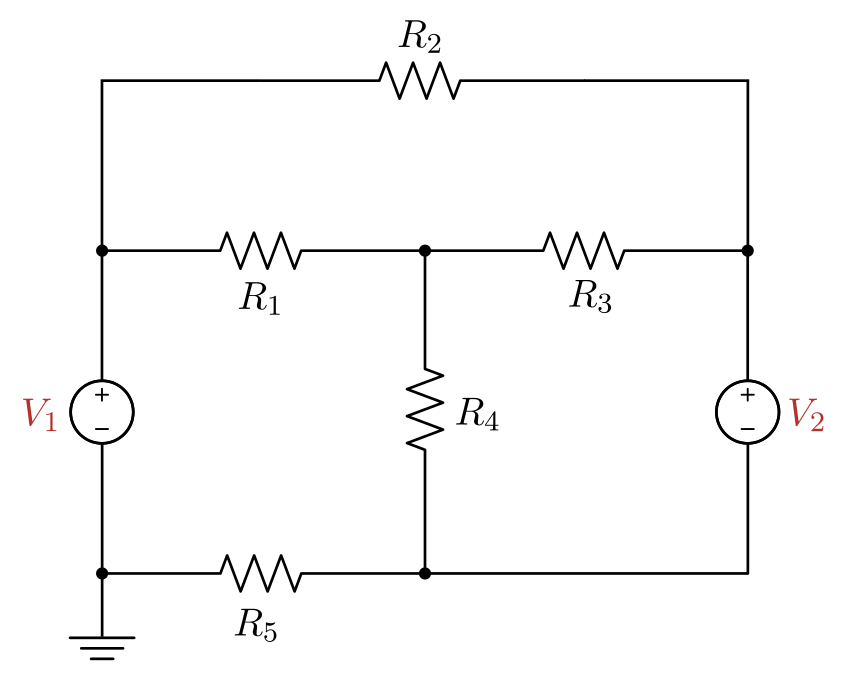

*Circuit diagram*

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 20 \ \Omega
\\
R_3 = 15 \ \Omega
\\
R_4 = 2 \ \Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 6 \ \text{V}
\end{array}$$


### **Step 1.** **Define the essential mesh currents.**

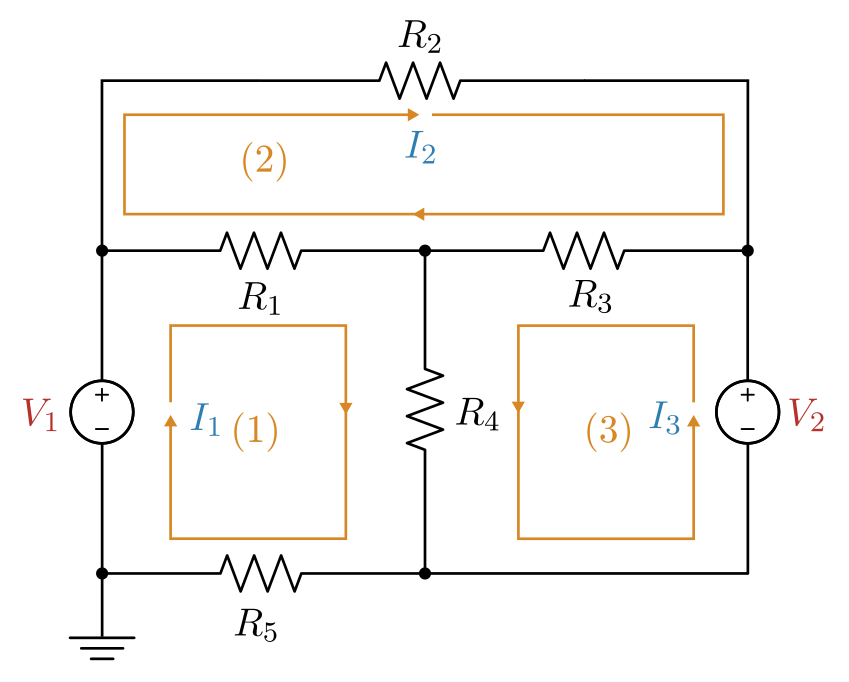

The current in each essential mesh is assigned a variable. In locations where the loops overlap, the current through the branch is the sum or difference of the mesh currents. The arbitrarily defined directions determine the signs of the currents.

### **Step 2. A**pply KVL.

**Mesh (1).** The first loop has four terms, one for each circuit element. By Kirchhoff's voltage law, the sum of voltages around the closed loop must be zero:


$$-V_1 + R_1\cdot(I_1 -I_2) + R_4\cdot( I_1 + I_3) + R_5 I_1 = 0$$


$I_1$ and $I_2$ were defined in opposing directions, so their difference is taken. $I_1$ and $I_3$, on the other hand, both travel in the same direction through $R_4$, so their sum is used.

**Mesh (2). **The second loop has three terms.


$$R_1\cdot(I_2 - I_1) + R_2 I_2 + R_3\cdot(I_2 + I_3) = 0$$


**Mesh (3). **The third loop also has three terms.


$$-V_2 + R_3\cdot(I_2 + I_3) + R_4\cdot(I_3 + I_1) = 0$$


### **Step 3. **Set up the matrix equation and solve.

**Set up the matrix equation.**

Before setting up the matrix equation, rewrite the equations in terms of the unknown $I_i$'s and move the constant terms to the right-hand side.


$$\begin{array}{rlcrl}
-V_1 + R_1\cdot(I_1 -I_2) + R_4\cdot( I_1 + I_3) + R_5 I_1 &= 0 &\rightarrow &(R_1 + R_4 + R_5) \cdot I_1 - R_1 I_2 + R_4 I_3 &= V_1
\\
R_1\cdot(I_2 - I_1) + R_2 I_2 + R_3\cdot(I_2 + I_3) &= 0 &\rightarrow &-R_1 I_1 + (R_1 + R_2 + R_3)\cdot I_2 + R_3 I_3 &= 0
\\
-V_2 + R_3\cdot(I_2 + I_3) + R_4\cdot(I_3 + I_1) &= 0 &\rightarrow & R_4 I_1 + R_3 I_2 + (R_3 + R_4) \cdot I_3 &= V_2
\end{array}$$
   

The matrix equation is created by defining the variable of unknown currents

    
$$\mathbf{I} = \left[ \begin{array}{l} I_1 \\ I_2 \\ I_3 \end{array} \right]$$
 

Then, the system is converted into matrix notation $\mathbf{A} \mathbf{I} = \mathbf{b}$, using the coefficients of the unknown $I_i$'s to build the coefficient matrix.

    
$$\left( \begin{array}{rl}  
R_1 + R_4 + R_5  & \ \ -R_1 &  \ \ R_4\\
-R_1 &\ \  R_1 + R_2 + R_3 &  \ \ R_3 \\
R_4 & \ \ R_3 &  \ \ R_3 + R_4 \\
\end{array} \right)
\left( \begin{array}{l} I_1 \\ I_2 \\ I_3 \end{array} \right)
=
\left( \begin{array}{l} V_1 \\ 0 \\ V_2 \end{array} \right)$$


**Solve the matrix equation in MATLAB.**

To solve the matrix system in MATLAB, start by defining the values of the resistors and voltage sources. 

% Given values
R1 = 10;
R2 = 20;
R3 = 15;
R4 = 2;
R5 = 330;
V1 = 1.5;
V2 = 6;

Next, define the coefficient matrix $\mathbf{A}$ and constant vector $\mathbf{b}$.

% Matrix system
A = [R1+R4+R5,      -R1,     R4; 
          -R1, R1+R2+R3,     R3;
           R4,       R3,  R3+R4];
b = [V1; 0; V2]

Then, solve the matrix system with the backslash (`\`) operator. To solve $\mathbf{A} \mathbf{I} = \mathbf{b}$, use

% Solution for the mesh currents
I = A\b

## **Simscape model analysis**

You can check your result by creating a model of the electrical circuit in Simscape and then measuring the currents. For this example, a model of the circuit has already been created. A virtual multimeter is included for taking measurements in the circuit. 

  **Activity. **Perform the following steps to validate the result of the mesh analysis.

1. Open the example model:

[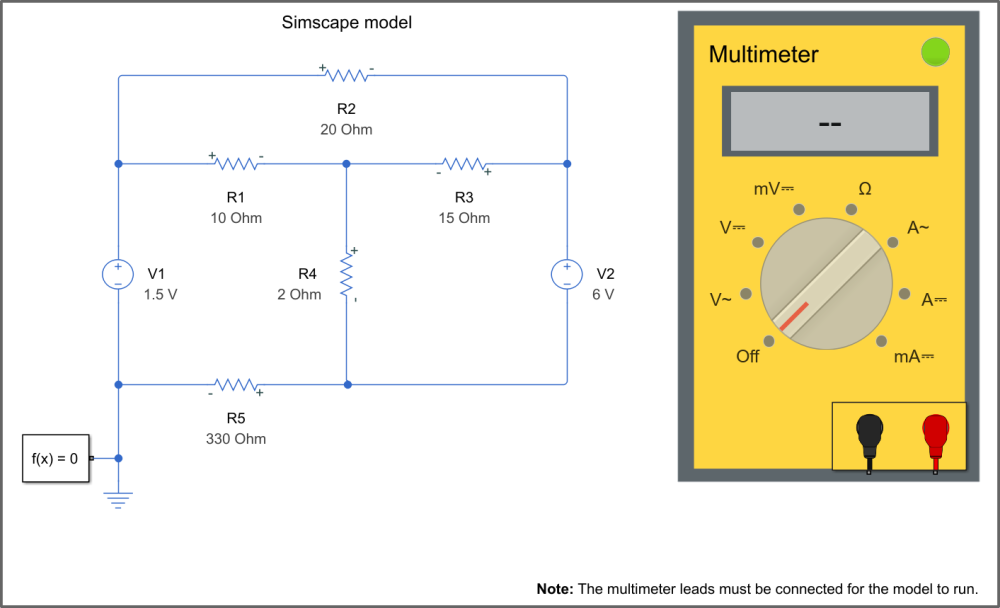](matlab: MeshAnalysisExample)

 [`MeshAnalysisExample.slx`](matlab: MeshAnalysisExample)

**Note: **Watch [this 2-minute instructional video](https://user-images.githubusercontent.com/81383420/145589989-f7ae4a32-cab3-405d-b7e8-476e34d697b5.mp4) to learn how to use the virtual multimeter.

2. In the next few steps, you will measure the third mesh current $I_3$ using the multimeter. To measure current, you must connect the multimeter in series with the branch. Start by deleting the existing circuit branch through which only $I_3$ flows. Left-click the branch and press the delete key.

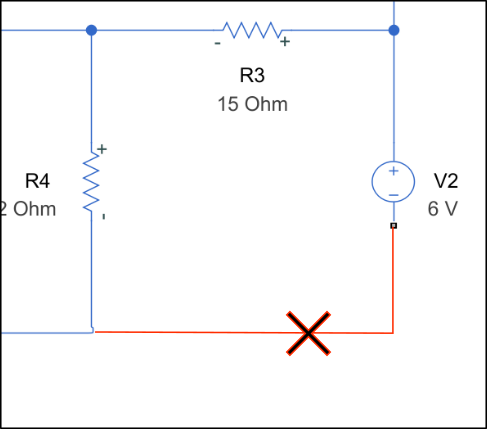

3. Drag the lead connections (at the bottom of the multimeter) to the circuit. Ensure that the leads are connected so that $I_3$ flows in the correct direction through the multimeter. By convention, current flows from positive (red lead) to negative (black lead). Connect the multimeter so that $I_3$ flows into the red lead and out of the black lead.

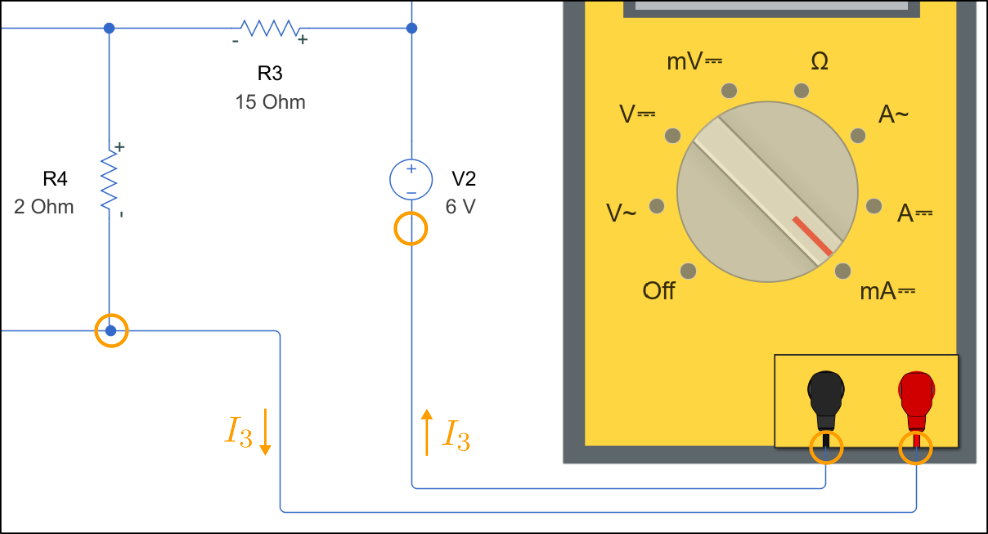

4. Run the model and then set the dial to measure mA⎓. If correct, there should be 501 mA flowing through this branch (since $I_3 = 0.501$ A). If the value is not 501 mA, verify that you have connected the leads to the correct nodes and are measuring mA⎓. After taking your measurement, stop the model.

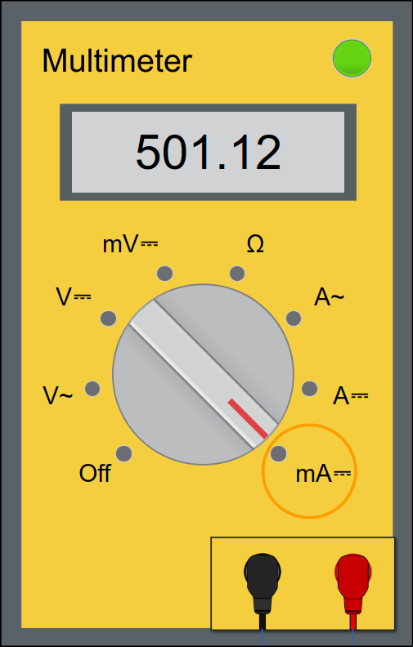

5. Repeat steps 2-4 to measure the mesh currents $I_1$ and $I_2$. If correct, you should find $I_1 = 3.46$ mA and $I_2 = 168$ mA, the currents calculated in the mesh analysis.

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)